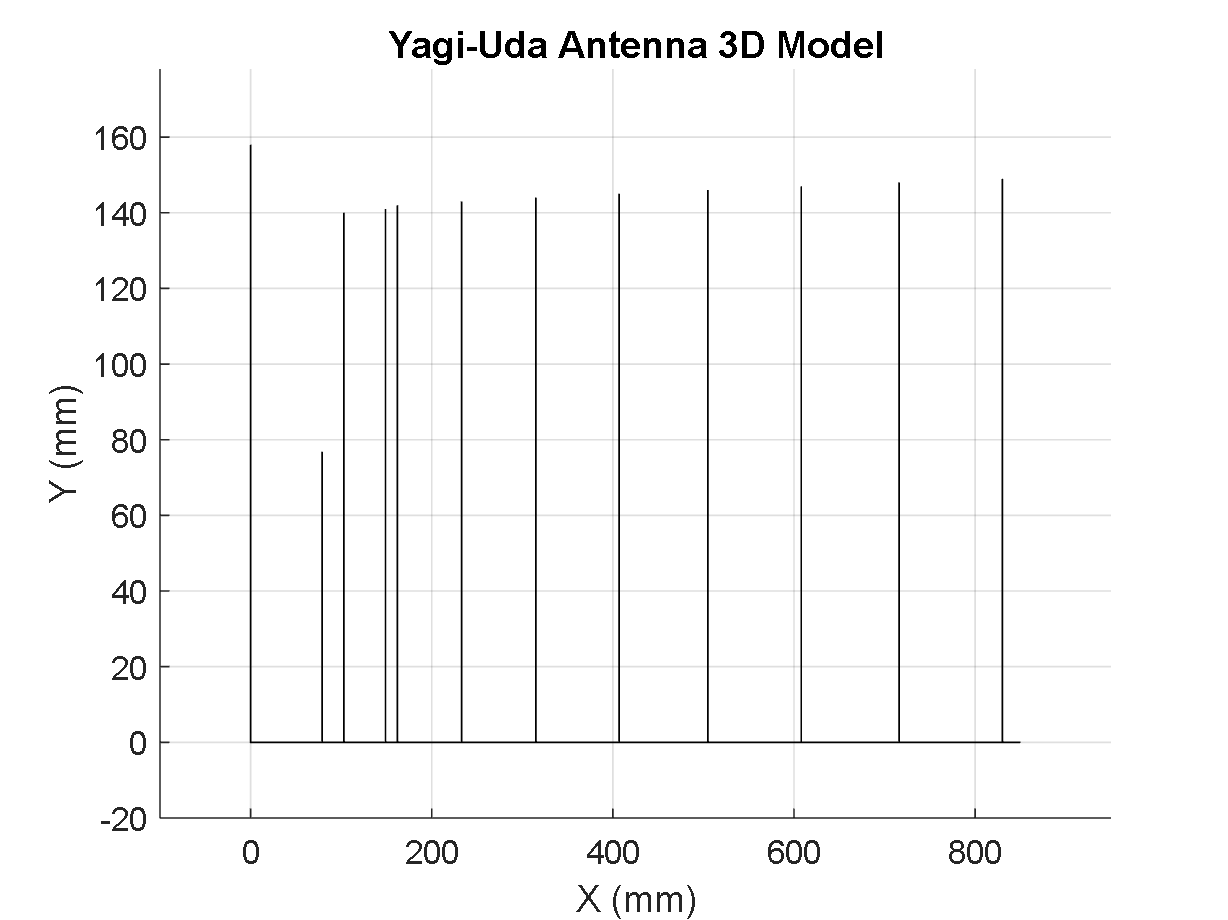

% Define parameters
boomLength = 850; % mm
diameter_d = 10; % mm
diameter_D = 20; % mm
numElements = 11;
gainRange = [11.5, 12.5]; % dBd

reflectorLength = 158; % mm
reflectorPosition_P = 0; % mm

dipolePosition_P = 79; % mm
dipoleLength = 76.8; % mm
halfWavelength = 163.8; % mm
reduction = 0.937;

% Director parameters
director_positions = [0, 103, 149, 162, 233, 315, 407, 505, 608, 716, 830]; % mm
director_lengths = [reflectorLength, 140, 141, 142, 143, 144, 145, 146, 147, 148, 149]; % mm

% Create Yagi-Uda Antenna
figure;
hold on;

% Plot boom
boom = patch([0, boomLength, boomLength, 0], [0, 0, 0, 0], [0, 0, 0, 0], 'k');

% Plot reflector
reflector = patch([reflectorPosition_P, reflectorPosition_P, reflectorPosition_P, reflectorPosition_P], ...
    [0, 0, reflectorLength, reflectorLength], [0, reflectorLength, reflectorLength, 0], 'r');

% Plot directors
for i = 1:numElements-1 % excluding the reflector
    % Plot the first side of the director
    director_side1 = patch([director_positions(i+1), director_positions(i+1), director_positions(i+1), director_positions(i+1)], ...
        [0, 0, director_lengths(i+1), director_lengths(i+1)], [0, director_lengths(i+1), director_lengths(i+1), 0], 'b');
    % Plot the second side of the director
    director_side2 = patch([director_positions(i+1), director_positions(i+1), director_positions(i+1), director_positions(i+1)], ...
        [0, 0, director_lengths(i+1), director_lengths(i+1)], [0, director_lengths(i+1), director_lengths(i+1), 0], 'b');
end

% Plot dipole
dipole = patch([dipolePosition_P, dipolePosition_P, dipolePosition_P, dipolePosition_P], ...
    [0, 0, dipoleLength, dipoleLength], [0, dipoleLength, dipoleLength, 0], 'g');

hold off;

% Set axis labels and title
xlabel('X (mm)');
ylabel('Y (mm)');
zlabel('Z (mm)');
title('Yagi-Uda Antenna 3D Model');
grid on;

% Adjust axes limits for better visibility
max_length = max([reflectorLength, max(director_lengths), dipoleLength]);
axis([-100, boomLength + 100, -20, max_length + 20, -20, max_length + 20]);


% Define parameters for radiation pattern
freq = 915e6; % Frequency in Hz

% Plot the radiation pattern
figure;
pattern(yagidesign, freq);

Unrecognized function or variable 'yagidesign'.


% Set title and labels
title('Radiation Pattern of Yagi-Uda Antenna');
xlabel('Azimuth (degrees)');
ylabel('Elevation (degrees)');
